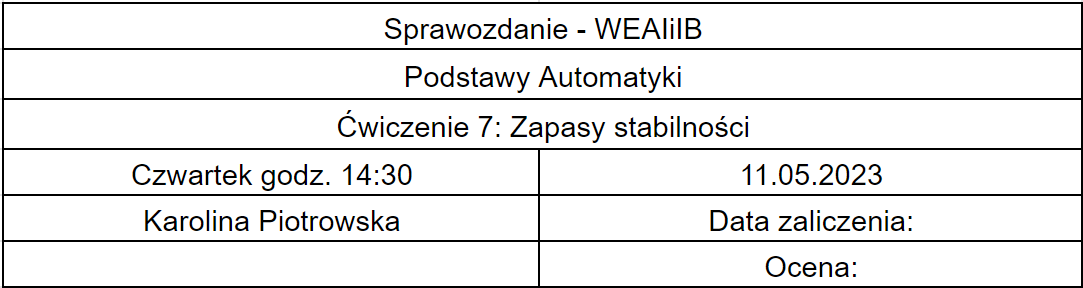

## Cel ćwiczenia

Ćwiczenie miało na celu przypomnienie zagadnień z zakresu zapasów stabilności 

## Wstęp teoretyczny

W ćwiczeniu rozważany jest zamknięty układ regulacji złożony z obiektu o transmitancji G(s) oraz regulatora liniowego ciągłego o transmitancji Gr(s). Rozważamy regulatory P, PI, PD oraz PID w wersji independent. Transmitancja układu jest równa Go(s) = Gr(s)G(s).

Rozważane transmitancje obiektu:

- 
$$G(s) = \frac{1}{s^3 + 3s^2 + 3s + 1}$$


- 
$$G(s) = \frac{1}{s^3 + 2s^2 + 2s + 1}$$


- 
$$G(s) = \frac{2}{s^3 + 3s^2 + 2s + 1}$$


- 
$$G(s) = \frac{1}{2s^3 + s^2 + s}$$


## Przebieg ćwiczenia

### Zadanie 1

Regulator P

Transmitancja obiektu: 

G =
 
            1
  ---------------------
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  4
 
Static gain.



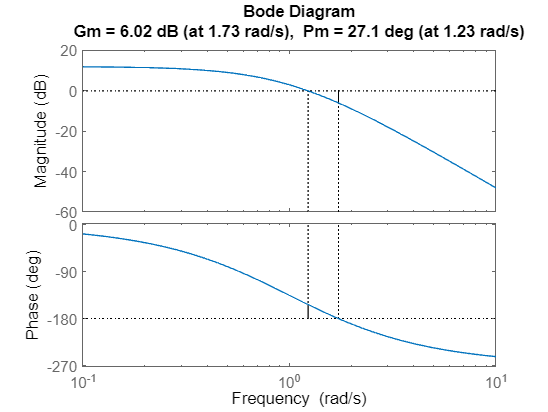

Zapas modułu: 

2

Zapas fazy: 

27.1366

Transmitancja obiektu: 

G =
 
            1
  ---------------------
  s^3 + 2 s^2 + 2 s + 1
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  1.5
 
Static gain.



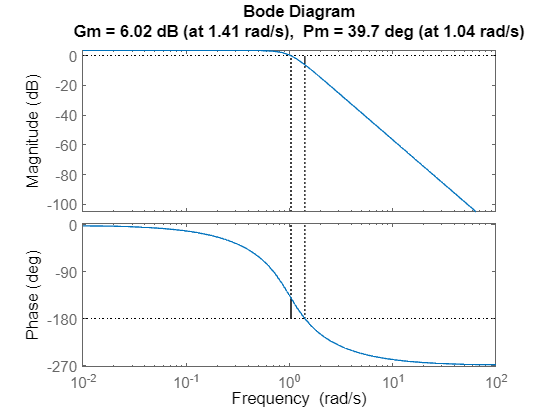

Zapas modułu: 

2

Zapas fazy: 

39.6836

Transmitancja obiektu: 

G =
 
            2
  ---------------------
  s^3 + 3 s^2 + 2 s + 1
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  1.25
 
Static gain.



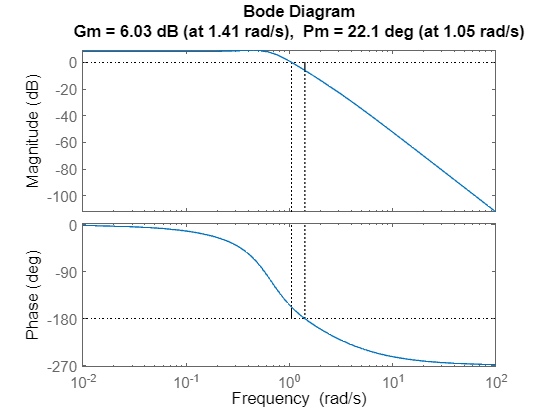

Zapas modułu: 

2.0012

Zapas fazy: 

22.0996

Transmitancja obiektu: 

G =
 
         1
  ---------------
  2 s^3 + s^2 + s
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  0.25
 
Static gain.



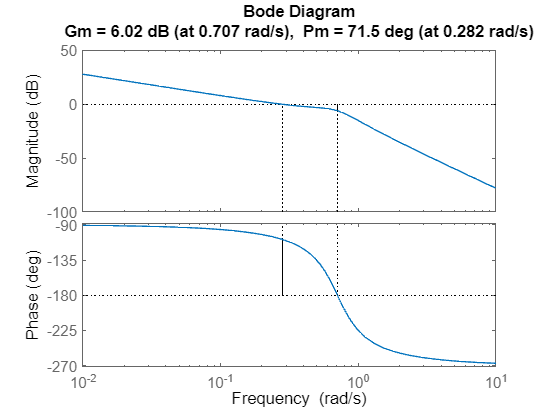

Zapas modułu: 

2

Zapas fazy: 

71.4778

G1 = tf([1], [1 3 3 1]);
G2 = tf([1], [1 2 2 1]);
G3 = tf([2], [1 3 2 1 ]);
G4 = tf([1], [2 1 1 0]);

Gi = [G1 G2 G3 G4];
k = [4.0005 1.5 5/4 1/4];

for i = 1:4
    fprintf('Transmitancja obiektu: ')
    G = Gi(i)
    fprintf('Transmitancja regulatora: ')
    Gr = tf(k(i), 1)

    figure
    margin(series(Gr, G))
    [gm, pm, c, d] = margin(series(Gr, G));
    fprintf('Zapas modułu: ')
    fprintf(num2str(gm))
    fprintf('Zapas fazy: ')
    fprintf(num2str(pm))    
end

### Zadanie 2

Regulator PI

Transmitancja obiektu: 

G =
 
            1
  ---------------------
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  4 s + 0.1
  ---------
      s
 
Continuous-time transfer function.



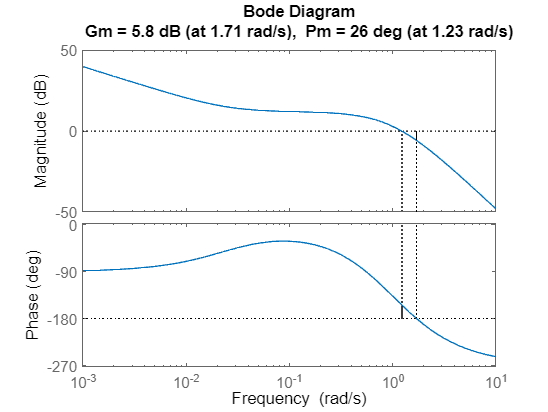

Zapas modułu: 

1.9502

Zapas fazy: 

25.9657

Transmitancja obiektu: 

G =
 
            1
  ---------------------
  s^3 + 2 s^2 + 2 s + 1
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  1.5 s + 0.1
  -----------
       s
 
Continuous-time transfer function.



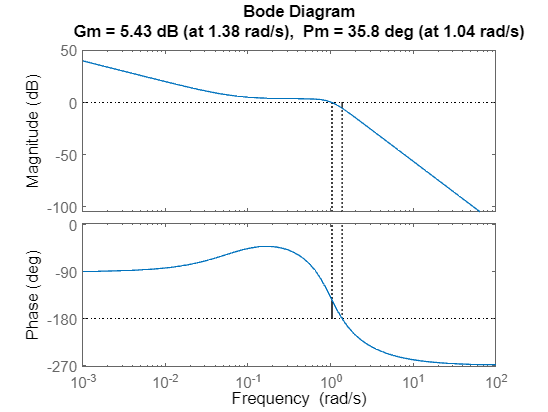

Zapas modułu: 

1.869

Zapas fazy: 

35.8373

Transmitancja obiektu: 

G =
 
            2
  ---------------------
  s^3 + 3 s^2 + 2 s + 1
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  1.25 s + 0.1
  ------------
       s
 
Continuous-time transfer function.



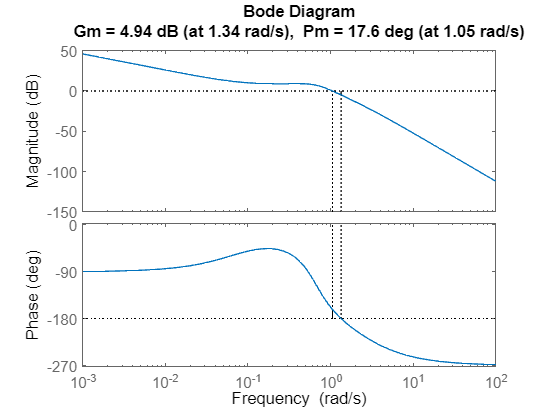

Zapas modułu: 

1.7652

Zapas fazy: 

17.6432

Transmitancja obiektu: 

G =
 
         1
  ---------------
  2 s^3 + s^2 + s
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  0.25 s + 0.1
  ------------
       s
 
Continuous-time transfer function.



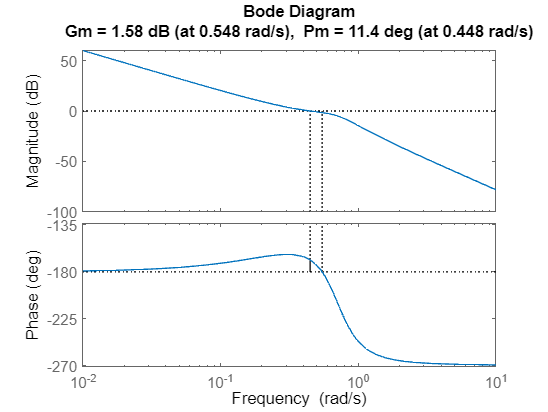

Zapas modułu: 

1.2

Zapas fazy: 

11.4055

Transmitancja obiektu: 

G =
 
            1
  ---------------------
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  4 s + 1
  -------
     s
 
Continuous-time transfer function.



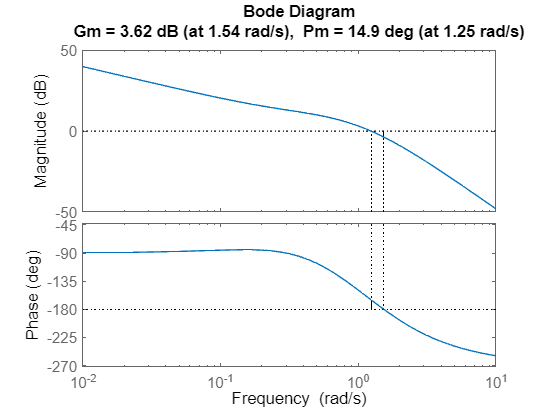

Zapas modułu: 

1.5175

Zapas fazy: 

14.885

Transmitancja obiektu: 

G =
 
            1
  ---------------------
  s^3 + 2 s^2 + 2 s + 1
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  1.5 s + 1
  ---------
      s
 
Continuous-time transfer function.



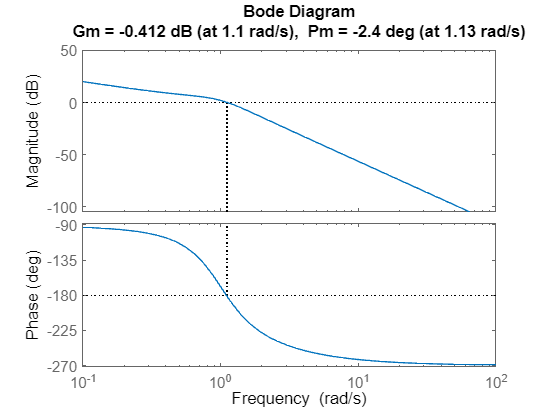

Zapas modułu: 

0.95367

Zapas fazy: 

-2.4014

Transmitancja obiektu: 

G =
 
            2
  ---------------------
  s^3 + 3 s^2 + 2 s + 1
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  1.25 s + 1
  ----------
      s
 
Continuous-time transfer function.



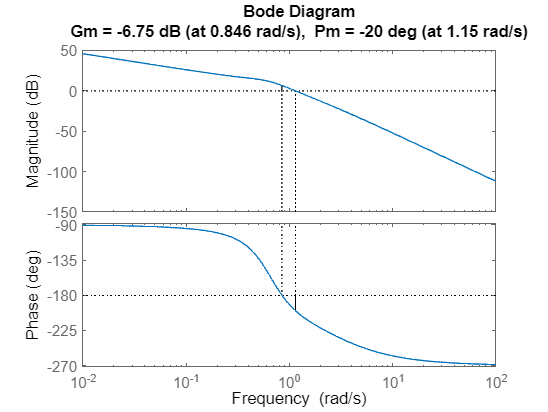

Zapas modułu: 

0.45982

Zapas fazy: 

-19.9681

Transmitancja obiektu: 

G =
 
         1
  ---------------
  2 s^3 + s^2 + s
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  0.25 s + 1
  ----------
      s
 
Continuous-time transfer function.



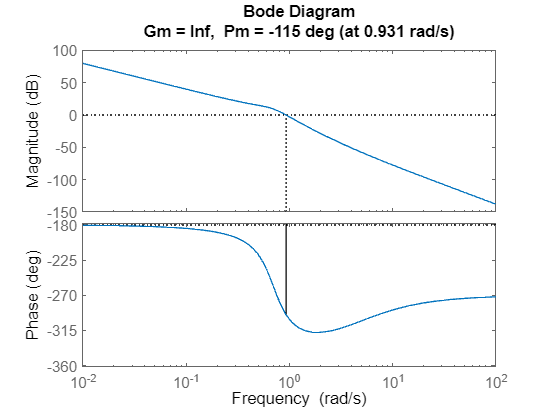

Zapas modułu: 

0

Zapas fazy: 

-115.1196

for alpha = [0.1 1]
    for i = 1:4
        fprintf('Transmitancja obiektu: ')
        G = Gi(i)
        fprintf('Transmitancja regulatora: ')
        Gr = tf([k(i) alpha], [1 0])

        figure
        margin(series(Gr, G))
        [gm, pm, c, d] = margin(series(Gr, G));
        fprintf('Zapas modułu: ')
        fprintf(num2str(gm))
        fprintf('Zapas fazy: ')
        fprintf(num2str(pm))
    end
end

### Zadanie 3

Regulator PD

Transmitancja obiektu: 

G =
 
            1
  ---------------------
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  0.5 s + 4
 
Continuous-time transfer function.



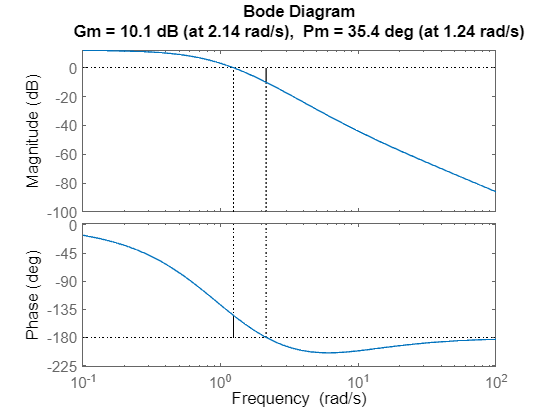

Zapas modułu: 

3.1994

Zapas fazy: 

35.403

Transmitancja obiektu: 

G =
 
            1
  ---------------------
  s^3 + 2 s^2 + 2 s + 1
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  0.5 s + 1.5
 
Continuous-time transfer function.



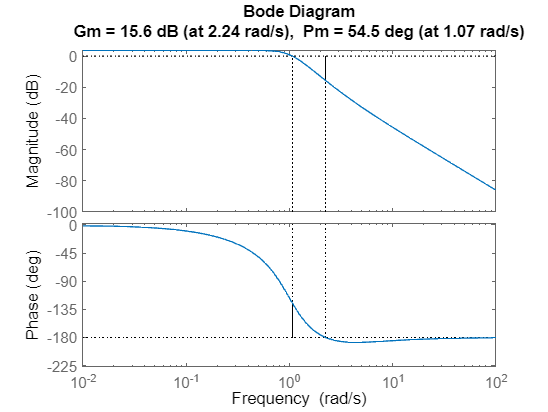

Zapas modułu: 

6.0002

Zapas fazy: 

54.4706

Transmitancja obiektu: 

G =
 
            2
  ---------------------
  s^3 + 3 s^2 + 2 s + 1
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  0.5 s + 1.25
 
Continuous-time transfer function.



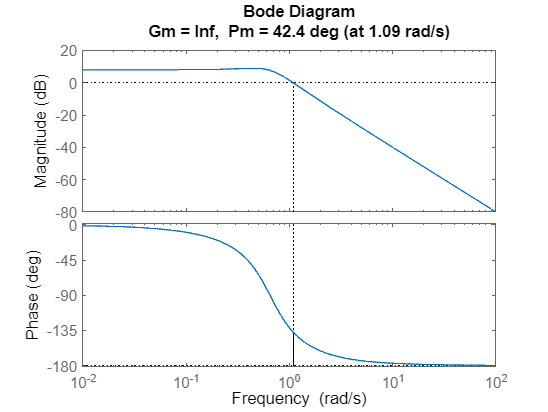

Zapas modułu: 

Inf

Zapas fazy: 

42.4408

Transmitancja obiektu: 

G =
 
         1
  ---------------
  2 s^3 + s^2 + s
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  0.5 s + 0.25
 
Continuous-time transfer function.



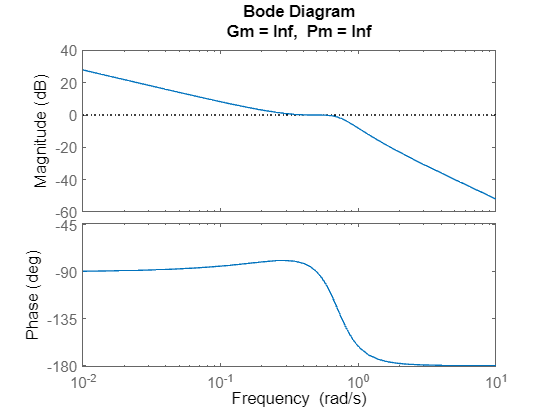

Zapas modułu: 

Inf

Zapas fazy: 

Inf

Transmitancja obiektu: 

G =
 
            1
  ---------------------
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  s + 4
 
Continuous-time transfer function.



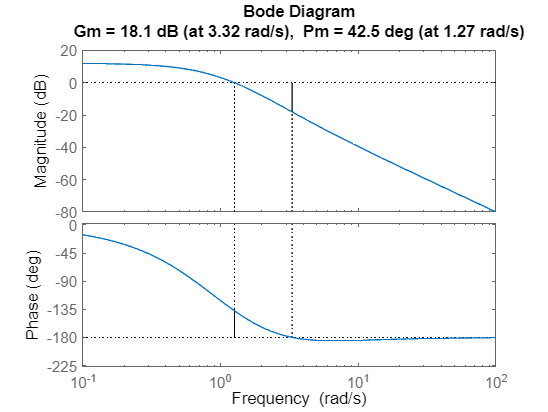

Zapas modułu: 

7.996

Zapas fazy: 

42.5038

Transmitancja obiektu: 

G =
 
            1
  ---------------------
  s^3 + 2 s^2 + 2 s + 1
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  s + 1.5
 
Continuous-time transfer function.



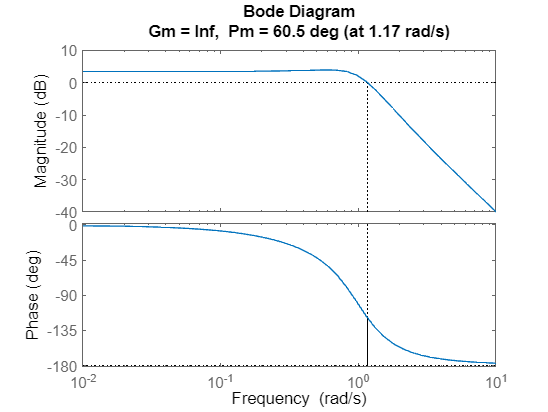

Zapas modułu: 

Inf

Zapas fazy: 

60.5323

Transmitancja obiektu: 

G =
 
            2
  ---------------------
  s^3 + 3 s^2 + 2 s + 1
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  s + 1.25
 
Continuous-time transfer function.



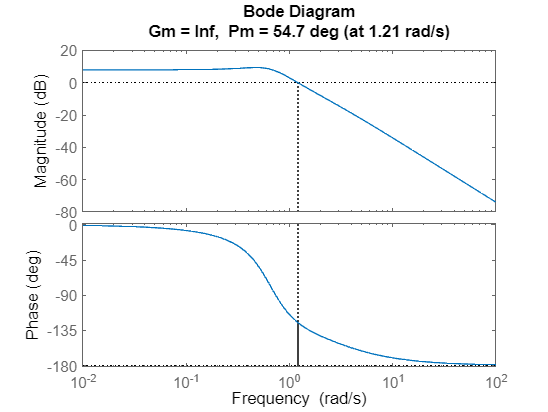

Zapas modułu: 

Inf

Zapas fazy: 

54.7073

Transmitancja obiektu: 

G =
 
         1
  ---------------
  2 s^3 + s^2 + s
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  s + 0.25
 
Continuous-time transfer function.



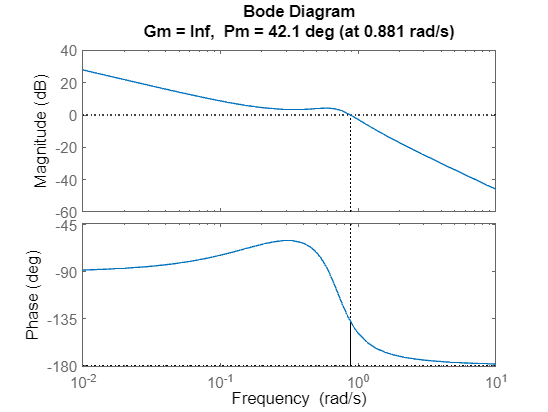

Zapas modułu: 

Inf

Zapas fazy: 

42.0872

for beta = [0.5 1]
    for i = 1:4
        fprintf('Transmitancja obiektu: ')
        G = Gi(i)
        fprintf('Transmitancja regulatora: ')
        Gr = tf([beta k(i)], 1)

        figure
        margin(series(Gr, G))
        [gm, pm, c, d] = margin(series(Gr, G));
        fprintf('Zapas modułu: ')
        fprintf(num2str(gm))
        fprintf('Zapas fazy: ')
        fprintf(num2str(pm))
    end
end

### Zadanie 4

Regulator PID

Transmitancja obiektu: 

G =
 
            1
  ---------------------
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  0.5 s^2 + 4 s + 0.1
  -------------------
           s
 
Continuous-time transfer function.



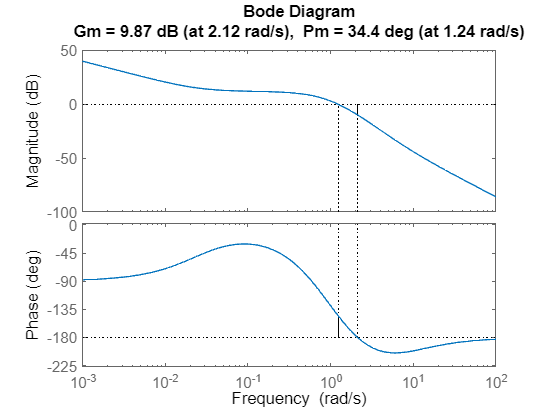

Zapas modułu: 

3.1161

Zapas fazy: 

34.3909

Transmitancja obiektu: 

G =
 
            1
  ---------------------
  s^3 + 2 s^2 + 2 s + 1
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  0.5 s^2 + 1.5 s + 0.1
  ---------------------
            s
 
Continuous-time transfer function.



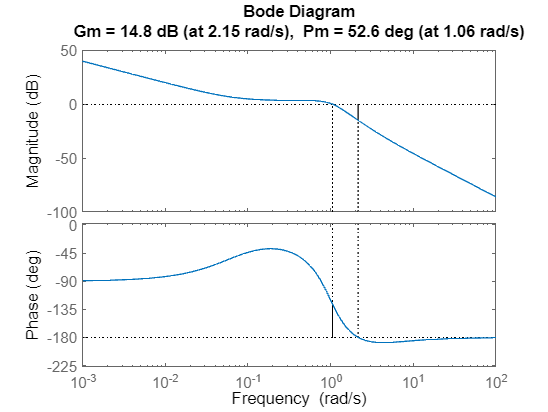

Zapas modułu: 

5.5245

Zapas fazy: 

52.5602

Transmitancja obiektu: 

G =
 
            2
  ---------------------
  s^3 + 3 s^2 + 2 s + 1
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  0.5 s^2 + 1.25 s + 0.1
  ----------------------
            s
 
Continuous-time transfer function.



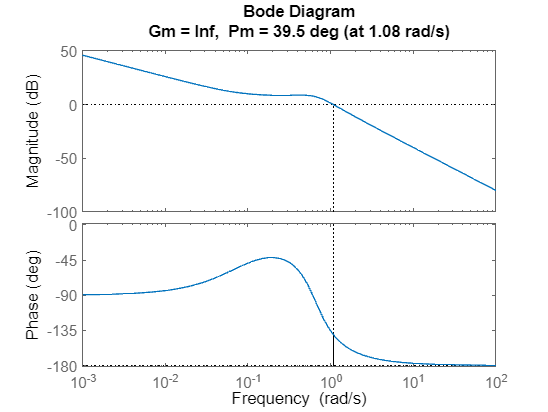

Zapas modułu: 

Inf

Zapas fazy: 

39.5159

Transmitancja obiektu: 

G =
 
         1
  ---------------
  2 s^3 + s^2 + s
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  0.5 s^2 + 0.25 s + 0.1
  ----------------------
            s
 
Continuous-time transfer function.



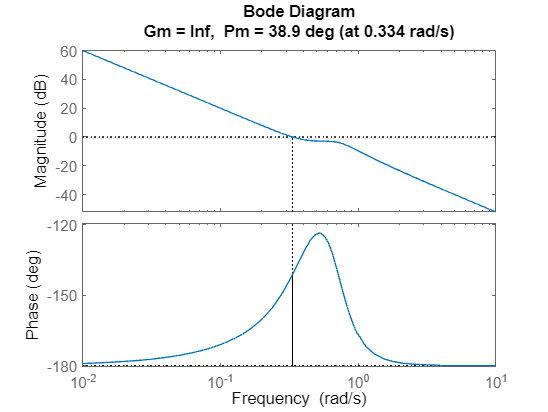

Zapas modułu: 

0

Zapas fazy: 

38.8882

Transmitancja obiektu: 

G =
 
            1
  ---------------------
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  s^2 + 4 s + 0.1
  ---------------
         s
 
Continuous-time transfer function.



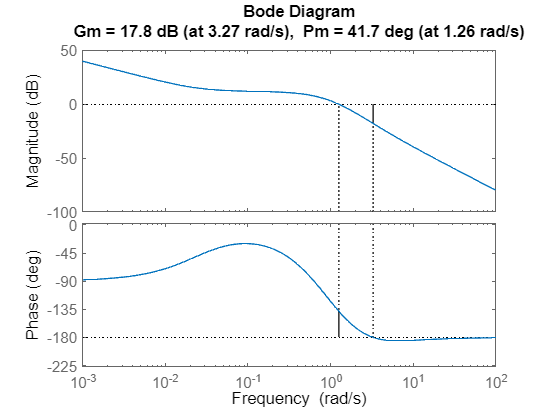

Zapas modułu: 

7.7782

Zapas fazy: 

41.6774

Transmitancja obiektu: 

G =
 
            1
  ---------------------
  s^3 + 2 s^2 + 2 s + 1
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  s^2 + 1.5 s + 0.1
  -----------------
          s
 
Continuous-time transfer function.



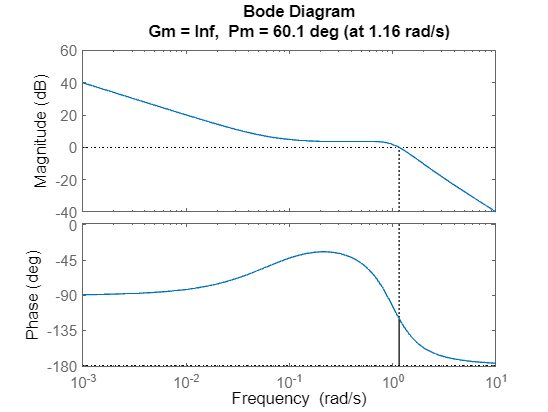

Zapas modułu: 

Inf

Zapas fazy: 

60.0626

Transmitancja obiektu: 

G =
 
            2
  ---------------------
  s^3 + 3 s^2 + 2 s + 1
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  s^2 + 1.25 s + 0.1
  ------------------
          s
 
Continuous-time transfer function.



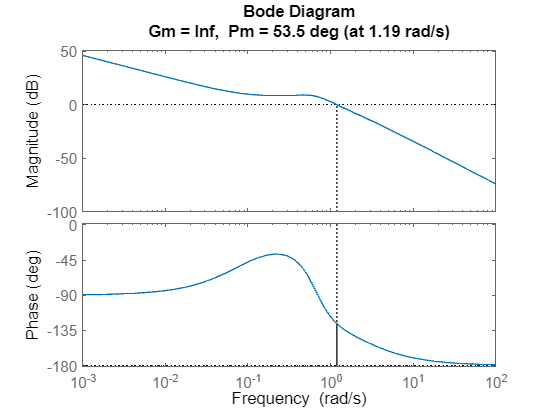

Zapas modułu: 

Inf

Zapas fazy: 

53.4605

Transmitancja obiektu: 

G =
 
         1
  ---------------
  2 s^3 + s^2 + s
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  s^2 + 0.25 s + 0.1
  ------------------
          s
 
Continuous-time transfer function.



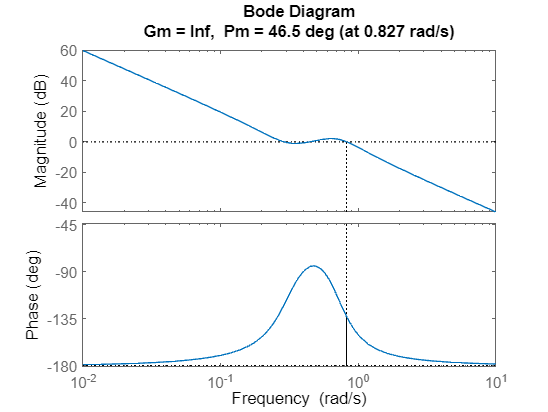

Zapas modułu: 

0

Zapas fazy: 

46.4855

Transmitancja obiektu: 

G =
 
            1
  ---------------------
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  0.5 s^2 + 4 s + 1
  -----------------
          s
 
Continuous-time transfer function.



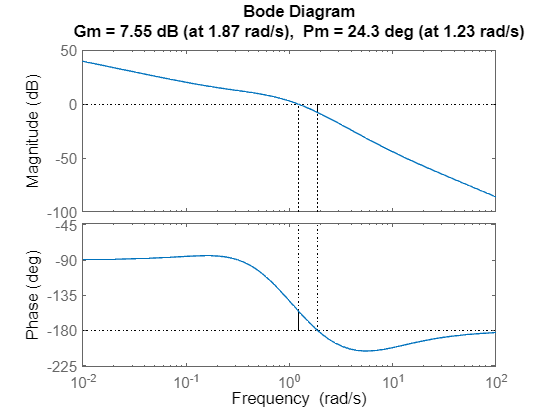

Zapas modułu: 

2.3852

Zapas fazy: 

24.3108

Transmitancja obiektu: 

G =
 
            1
  ---------------------
  s^3 + 2 s^2 + 2 s + 1
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  0.5 s^2 + 1.5 s + 1
  -------------------
           s
 
Continuous-time transfer function.



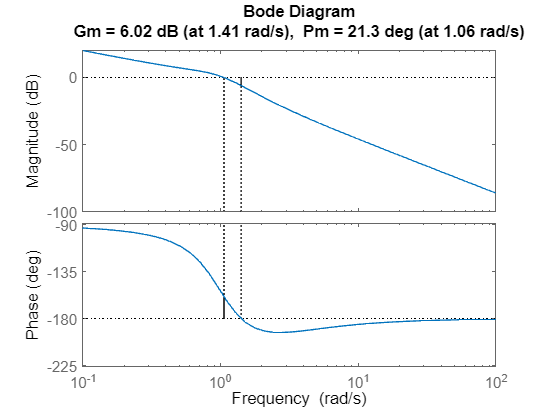

Zapas modułu: 

2

Zapas fazy: 

21.251

Transmitancja obiektu: 

G =
 
            2
  ---------------------
  s^3 + 3 s^2 + 2 s + 1
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  0.5 s^2 + 1.25 s + 1
  --------------------
           s
 
Continuous-time transfer function.



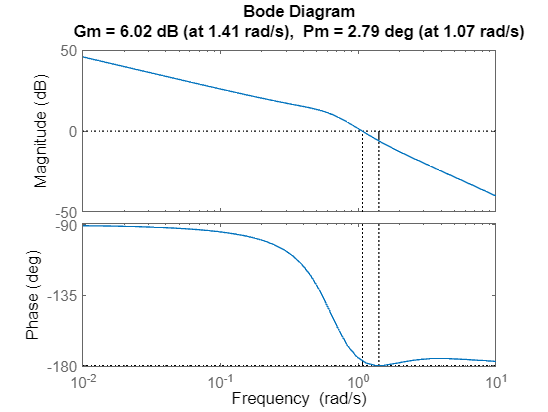

Zapas modułu: 

2

Zapas fazy: 

2.787

Transmitancja obiektu: 

G =
 
         1
  ---------------
  2 s^3 + s^2 + s
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  0.5 s^2 + 0.25 s + 1
  --------------------
           s
 
Continuous-time transfer function.



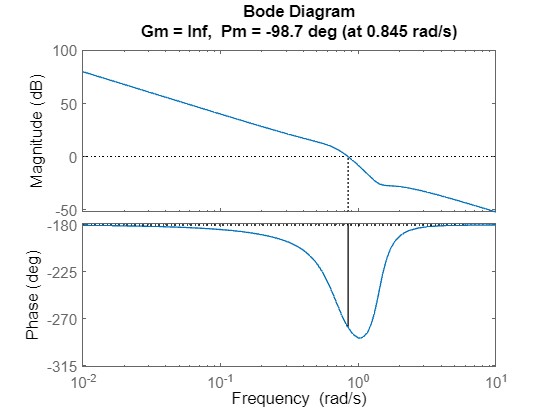

Zapas modułu: 

0

Zapas fazy: 

-98.6901

Transmitancja obiektu: 

G =
 
            1
  ---------------------
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  s^2 + 4 s + 1
  -------------
        s
 
Continuous-time transfer function.



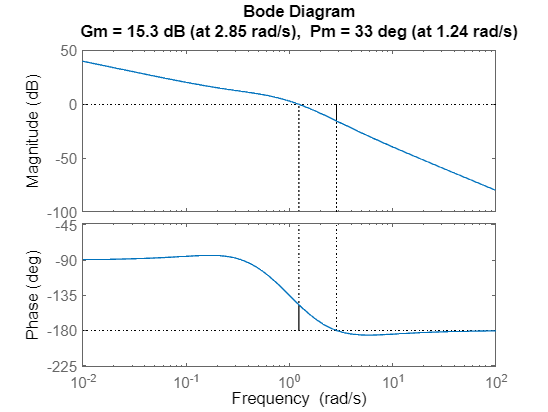

Zapas modułu: 

5.8402

Zapas fazy: 

32.9828

Transmitancja obiektu: 

G =
 
            1
  ---------------------
  s^3 + 2 s^2 + 2 s + 1
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  s^2 + 1.5 s + 1
  ---------------
         s
 
Continuous-time transfer function.



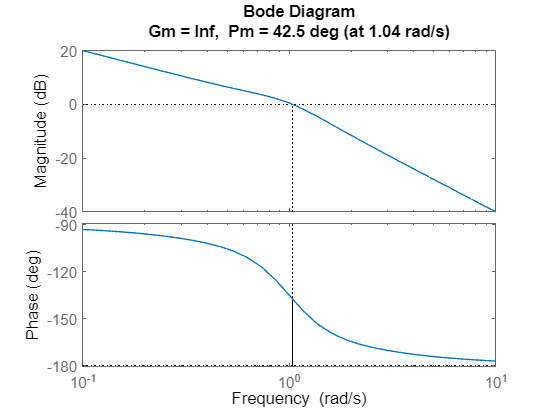

Zapas modułu: 

Inf

Zapas fazy: 

42.4687

Transmitancja obiektu: 

G =
 
            2
  ---------------------
  s^3 + 3 s^2 + 2 s + 1
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  s^2 + 1.25 s + 1
  ----------------
         s
 
Continuous-time transfer function.



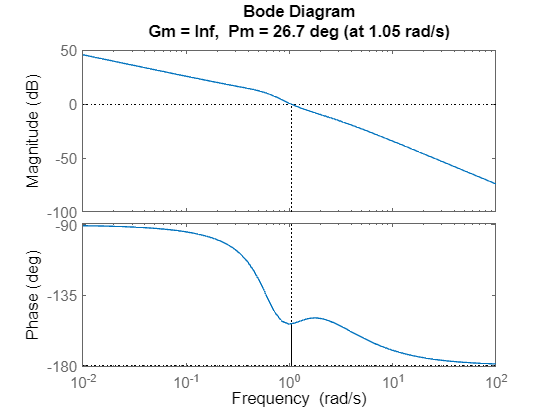

Zapas modułu: 

Inf

Zapas fazy: 

26.6936

Transmitancja obiektu: 

G =
 
         1
  ---------------
  2 s^3 + s^2 + s
 
Continuous-time transfer function.



Transmitancja regulatora: 

Gr =
 
  s^2 + 0.25 s + 1
  ----------------
         s
 
Continuous-time transfer function.



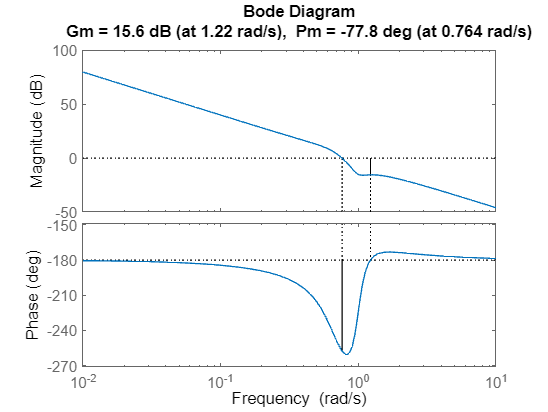

Zapas modułu: 

6

Zapas fazy: 

-77.754

for alpha = [0.1 1]
    for beta = [0.5 1]
        for i = 1:4
            fprintf('Transmitancja obiektu: ')
            G = Gi(i)
            fprintf('Transmitancja regulatora: ')
            Gr = tf([beta k(i) alpha], [1 0])
    
            figure
            margin(series(Gr, G))
            [gm, pm, c, d] = margin(series(Gr, G));
            fprintf('Zapas modułu: ')
            fprintf(num2str(gm))
            fprintf('Zapas fazy: ')
            fprintf(num2str(pm))
        end
    end
end

## Wnioski

Regulatrory P oraz PI zmiejszają zapas stabilności. Regulatory PD oraz PID zwiększają zapas stabilności.